clear
clc
rng default  % 保证结果运行一致

load('ResNet_3_classes.mat','model')
inputSize= model. Layers(1).InputSize

inputSize =    224   224     3


class_names = model. Layers(end).ClassNames ;
num_classes = numel(class_names) ;
disp(class_names(randperm(num_classes, 10)))

    {'beignets'         }
    {'baby_back_ribs'   }
    {'bibimbap'         }
    {'beet_salad'       }
    {'bread_pudding'    }
    {'apple_pie'        }
    {'beef_carpaccio'   }
    {'baklava'          }
    {'beef_tartare'     }
    {'breakfast_burrito'}



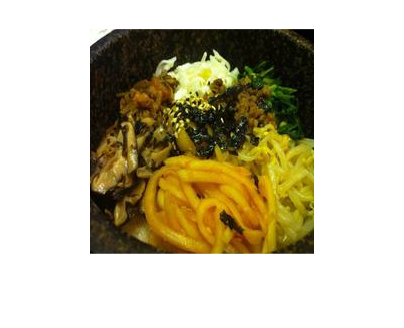

Img = imread('359589.jpg');
figure
imshow(Img)

Img = imresize(Img, inputSize(1: 2));
figure
imshow(Img)

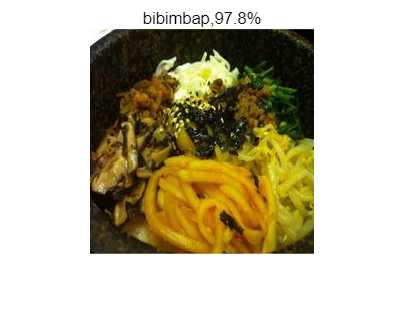

[labels, scores] = classify(model, Img);
figure
imshow(Img)
title(string(labels)+","+ num2str(100*scores(class_names == labels),3)+"%");

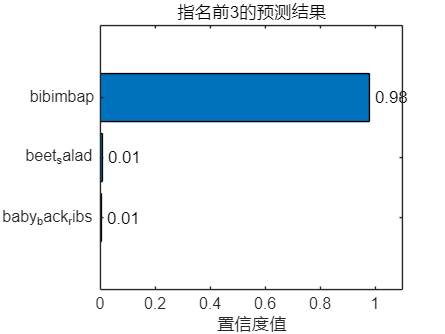

[~,idx] = sort(scores, 'descend');
idx=idx(3:-1:1);
classNamesTop = model.Layers(end).ClassNames(idx);
scoresTop = scores(idx);
figure
%绘制条形图显示置信度值
mybar=barh(scoresTop);
xlim([0 1.1])
yticklabels(classNamesTop)
xtips = mybar(1) .YEndPoints + 0.02; 
ytips =mybar(1) .XEndPoints ;
labels = string(round(mybar(1).YData, 2));
text(xtips ,ytips ,labels, 'VerticalAlignment','middle')
title('指名前3的预测结果')
xlabel('置信度值')